# Faza 4

% set(groot, 'DefaultFigureUnits', 'pixels');
set(groot, 'DefaultFigurePosition', [20, 20, 1500, 1000]);
% Instructiune initializare proprietati pentru toate graficele (utila sa
% pot sa maximizez dimensiunile ferestrelor. Asta e folosita pentru
% afisarea graficelor intr-un mod corespunzator in live script, si pentru
% export in PDF. Eventual aceste marimi pot fi modificate.
load('criterii_faza4.mat');

% Se vor genera cele mai bune ferestre pentru toate tipurile de ferestre
% mentionate in "best_filter_4.m".
Delta_s = Delta_s / 100;
Delta_p = Delta_p / 100;
% [h_box, om_c_box, d_pr_box, d_sr_box] = ...
%     best_filter_4(omega_p, omega_s, Delta_p, Delta_s, 'dreptunghiular');
% [h_triang, om_c_triang, d_pr_triang, d_sr_triang] = ...
%     best_filter_4(omega_p, omega_s, Delta_p, Delta_s, 'triunghiular');
[h_blackman, om_c_blackman, d_pr_blackman, d_sr_blackman] = ...
    best_filter_4(omega_p, omega_s, Delta_p, Delta_s, 'blackman');
[h_hamming, om_c_hamming, d_pr_hamming, d_sr_hamming] = ...
    best_filter_4(omega_p, omega_s, Delta_p, Delta_s, 'hamming');
[h_hanning, om_c_hanning, d_pr_hanning, d_sr_hanning] = ...
    best_filter_4(omega_p, omega_s, Delta_p, Delta_s, 'hanning');
beta_init = 1;
[h_kaiser, om_c_kaiser, d_pr_kaiser, d_sr_kaiser] = ...
    best_filter_4(omega_p, omega_s, Delta_p, Delta_s, 'kaiser', beta_init);
for beta = 1.25 : 0.25 : 12
    [h_temp, om_c_temp, d_pr_temp, d_sr_temp] = ...
        best_filter_4(omega_p, omega_s, Delta_p, Delta_s, 'kaiser', beta);
    if length(h_kaiser) > length(h_temp)
        h_kaiser = h_temp;
        om_c_kaiser = om_c_temp;
        d_pr_kaiser = d_pr_temp;
        d_sr_kaiser = d_sr_temp;
        beta_init = beta;
    else 
        if length(h_kaiser) == length(h_temp)
            if d_pr_kaiser + d_sr_kaiser > d_pr_temp + d_sr_temp
                h_kaiser = h_temp;
                om_c_kaiser = om_c_temp;
                d_pr_kaiser = d_pr_temp;
                d_sr_kaiser = d_sr_temp;
                beta_init = beta;
            end
        end
    end
end
r_init = 20;
[h_chebysev, om_c_chebysev, d_pr_chebysev, d_sr_chebysev] = ...
    best_filter_4(omega_p, omega_s, Delta_p, Delta_s, 'chebysev', r_init);
for r = 21 : 110
    [h_temp, om_c_temp, d_pr_temp, d_sr_temp] = ...
        best_filter_4(omega_p, omega_s, Delta_p, Delta_s, 'chebysev', r);
    if length(h_chebysev) > length(h_temp)
        h_chebysev = h_temp;
        om_c_chebysev = om_c_temp;
        d_pr_chebysev = d_pr_temp;
        d_sr_chebysev = d_sr_temp;
        r_init = r;
    else 
        if length(h_chebysev) == length(h_temp)
            if d_pr_chebysev + d_sr_chebysev > d_pr_temp + d_sr_temp
                h_chebysev = h_temp;
                om_c_chebysev = om_c_temp;
                d_pr_chebysev = d_pr_temp;
                d_sr_chebysev = d_sr_temp;
                r_init = r;
            end
        end
    end
end
L_init = 0.2;
[h_lanczos, om_c_lanczos, d_pr_lanczos, d_sr_lanczos] = ...
    best_filter_4(omega_p, omega_s, Delta_p, Delta_s, 'lanczos', L_init);
for L = 0.55 : 0.05 : 1.5
    [h_temp, om_c_temp, d_pr_temp, d_sr_temp] = ...
        best_filter_4(omega_p, omega_s, Delta_p, Delta_s, 'lanczos', L);
    if length(h_lanczos) > length(h_temp)
        h_lanczos = h_temp;
        om_c_lanczos = om_c_temp;
        d_pr_lanczos = d_pr_temp;
        d_sr_lanczos = d_sr_temp;
        L_init = L;
    else 
        if length(h_lanczos) == length(h_temp)
            if d_pr_lanczos + d_sr_lanczos > d_pr_temp + d_sr_temp
                h_lanczos = h_temp;
                om_c_lanczos = om_c_temp;
                d_pr_lanczos = d_pr_temp;
                d_sr_lanczos = d_sr_temp;
                L_init = L;
            end
        end
    end
end
alpha_init = 10;
[h_tukey, om_c_tukey, d_pr_tukey, d_sr_tukey] = ...
    best_filter_4(omega_p, omega_s, Delta_p, Delta_s, 'tukey', alpha_init);
for alpha = 11 : 80
    [h_temp, om_c_temp, d_pr_temp, d_sr_temp] = ...
        best_filter_4(omega_p, omega_s, Delta_p, Delta_s, 'tukey', alpha);
    if length(h_tukey) > length(h_temp)
        h_tukey = h_temp;
        om_c_tukey = om_c_temp;
        d_pr_tukey = d_pr_temp;
        d_sr_tukey = d_sr_temp;
        alpha_init = alpha;
    else 
        if length(h_tukey) == length(h_temp)
            if d_pr_tukey + d_sr_tukey > d_pr_temp + d_sr_temp
                h_tukey = h_temp;
                om_c_tukey = om_c_temp;
                d_pr_tukey = d_pr_temp;
                d_sr_tukey = d_sr_temp;
                alpha_init = alpha;
            end
        end
    end
end

Dupa studierea rezultatelor generate pentru toate tipurile de ferestre, filtrele cele mai bune, in ordine descrescatoare, sunt: Kaiser, Chebysev, Lanczos! Se iau in considerare in functie de lungimea secventei de pondere generate.

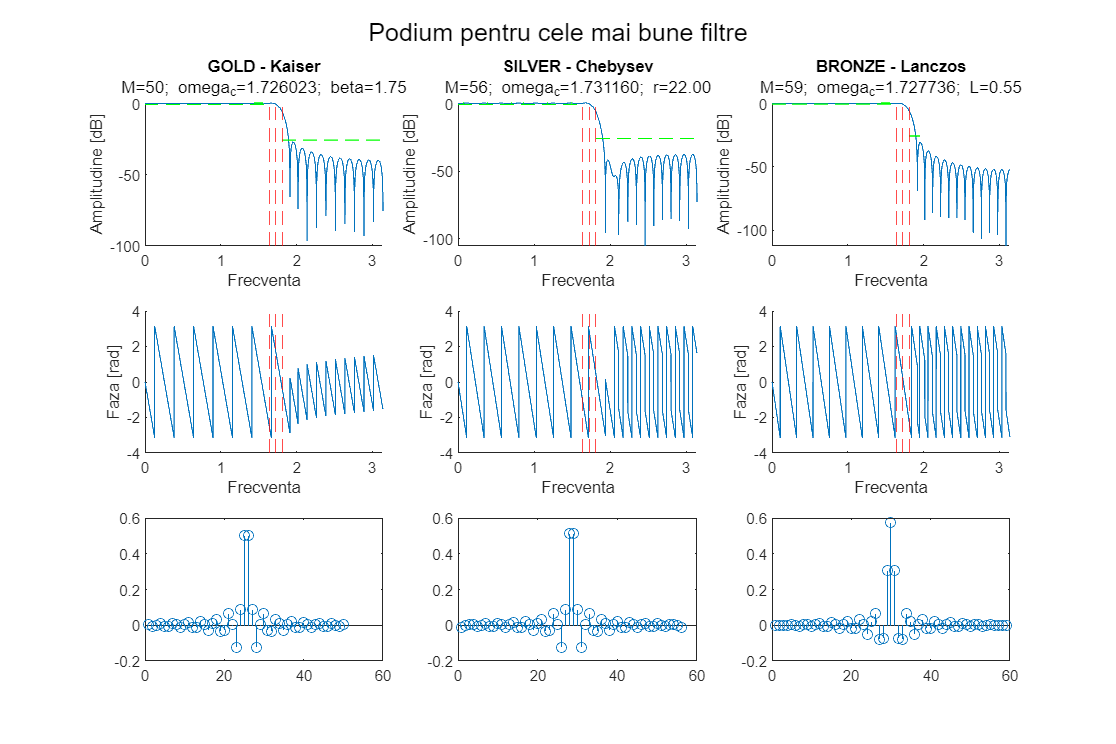

[H_kaiser, om] = freqz(h_kaiser, 1, 5000);
[H_chebysev] = freqz(h_chebysev, 1, 5000);
[H_lanczos] = freqz(h_lanczos, 1, 5000);
om_p = om(om <= omega_p);
om_s = om(om >= omega_s);
podium = figure('Name', 'Podium filtre');
subplot(3, 3, 1, 'NextPlot', 'add');
plot(om, mag2db(abs(H_kaiser)));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(om_c_kaiser, 'r--');
plot(om_p, ones(1, length(om_p)) * mag2db(1 - Delta_p), 'g--');
plot(om_p, ones(1, length(om_p)) * mag2db(1 + Delta_p), 'g--');
plot(om_s, ones(1, length(om_s)) * mag2db(Delta_s), 'g--');
hold off
xlabel('Frecventa');
ylabel('Amplitudine [dB]');
title("GOLD - Kaiser", sprintf("M=%d; omega_c=%f; beta=%.2f", length(h_kaiser), om_c_kaiser, beta_init));
subplot(3, 3, 2, 'NextPlot', 'add');
plot(om, mag2db(abs(H_chebysev)));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(om_c_chebysev, 'r--');
plot(om_p, ones(1, length(om_p)) * mag2db(1 - Delta_p), 'g--');
plot(om_p, ones(1, length(om_p)) * mag2db(1 + Delta_p), 'g--');
plot(om_s, ones(1, length(om_s)) * mag2db(Delta_s), 'g--');
hold off
xlabel('Frecventa');
ylabel('Amplitudine [dB]');
title("SILVER - Chebysev", sprintf("M=%d; omega_c=%f; r=%.2f", length(h_chebysev), om_c_chebysev, r_init));
subplot(3, 3, 3, 'NextPlot', 'add');
plot(om, mag2db(abs(H_lanczos)));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(om_c_lanczos, 'r--');
plot(om_p, ones(1, length(om_p)) * mag2db(1 - Delta_p), 'g--');
plot(om_p, ones(1, length(om_p)) * mag2db(1 + Delta_p), 'g--');
plot(om_s, ones(1, length(om_s)) * mag2db(Delta_s), 'g--');
hold off
xlabel('Frecventa');
ylabel('Amplitudine [dB]');
title("BRONZE - Lanczos", sprintf("M=%d; omega_c=%f; L=%.2f", length(h_lanczos), om_c_lanczos, L_init));

subplot(3, 3, 4, 'NextPlot', 'add');
plot(om, angle(H_kaiser));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(om_c_kaiser, 'r--');
hold off
xlabel('Frecventa');
ylabel('Faza [rad]');
subplot(3, 3, 5, 'NextPlot', 'add');
plot(om, angle(H_chebysev));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(om_c_chebysev, 'r--');
hold off
xlabel('Frecventa');
ylabel('Faza [rad]');
subplot(3, 3, 6, 'NextPlot', 'add');
plot(om, angle(H_lanczos));
hold on
xline(omega_p, 'r--');
xline(omega_s, 'r--');
xline(om_c_lanczos, 'r--');
hold off
xlabel('Frecventa');
ylabel('Faza [rad]');

subplot(3, 3, 7);
stem(h_kaiser);
subplot(3, 3, 8);
stem(h_chebysev);
subplot(3, 3, 9);
stem(h_lanczos);

sgtitle('Podium pentru cele mai bune filtre');

% Export date
h = h_kaiser;
omega_c = om_c_kaiser;
Delta_p = Delta_p * 100;
Delta_s = Delta_s * 100;
save('BONTAS_Cezar_Octavian_F#4.mat', 'h_kaiser', 'omega_p', 'omega_s', 'Delta_p', 'Delta_s', 'om_c_kaiser');

Cum ne-am asteptat, Kaiser este pe primul loc. In mod surprinzator, fata de clasamentul facut in faza 2, Chebysev se afla pe locul 2 (in locul lui Blackman, care a performat foarte prost, in ciuda asemanarilor cu Kaiser) si Lanczos, care cel mai probabil a beneficiat de micsorarea deschiderii ferestrei (in testele din faza 2, L = 6, aici raza a fost mult mai mica, in jurul zonei in care L este cel mai des utilizat [0.8, 1.2]).